# RUL

## RUL estimation using Residual similarity model

### Generation Prognostic data from model

Generate response data from the model. In further steps this dataset can be imported as data ensemble format.

clc; clear all; close all;
addpath("featuretables/"); addpath("functions/");
addpath("../models/")
run("params.m");

fault_code = "1100001"

Healthy system behavior 


disp('[INFO] Parameters were loaded');

[INFO] Parameters were loaded


%%
output_path = '../data/data_gen_mdl_air_leak';
model = 'model_equation_simply_valves';

#### Air leak from B chamber

In this section air leak fault is simulated. Assuming that air leak discharge coefficient has expotential growing. Simulated data has different number of cycles, that represent different air leak fault dynamic. Simulated data represents run-to-failure data for different stands. Where ID represent identification number of stand.

generate_data = 0;
id_max = 25;
if generate_data
    air_leak = 1;

    for i = 0:1:id_max
        output_path = '../data/data_gen_rul/id_' + string(i) +'/';
        
        load_system(model);
        open_system(model);
        runParallel = 1;
        
        
        % Run using Parallel Computing Toolbox
        if runParallel && isempty(gcp('nocreate'))
            parpool([2,6]);
        end
        
        % Parameters changing in the time. For system behavior simulation purposes.
        C_leak_values = linspace(1e-5, (1+(2-1)*rand)*1e-3, (100+100*rand));
        C_leak_values = C_leak_values.^2 + rand*C_leak_values.^3;
        for k = 1:numel(C_leak_values)
            C_leak_values(k) = C_leak_values(k) + (1+(8-1)*rand)*0.01*C_leak_values(k);   
        end
        hold on
        plot(C_leak_values)
        title("Dischrge coefficient air leak")
        xlabel("Cycle")
        ylabel("Discharge coefficient")

        
        for j = 1:numel(C_leak_values)
            tmp = Simulink.SimulationInput(model);
            tmp = setVariable(tmp, 'C_leak', C_leak_values(j));
            tmp = setVariable(tmp, 'cycle', j);
            tmp = setVariable(tmp, 'id', i);
            simin(j) = tmp;
        end
        
        if ~exist(fullfile(pwd, output_path), 'dir')
            mkdir(fullfile(pwd, output_path))
        end
        
        [status,e] = generateSimulationEnsemble(simin, ...
            fullfile(pwd, output_path), 'UseParallel', runParallel);
        if status
            disp("[INFO] Data was successfully generated")
        else
            warning("Fault in data generation")
        end
        clear simin
    end
end

clear all;
addpath("featuretables/"); addpath("functions/");
addpath("../utils/")
output_path = '../data/data_gen_rul';
ensemble = simulationEnsembleDatastore(output_path);
ensemble.SelectedVariables = ["ID"; "Cycle"];
fix = 0;
if fix
    ensemble = handler_fix_datastore(ensemble);
end


reset(ensemble)
ensemble.SelectedVariables = ["Time"; ... 
                              "Id"; ...
                              "LeverPosition"; ...
                              "LeverVelocity"; ...
                              "FlowContraction"; ...
                              "FlowExtrusion"; ...
                              ];
member = read(ensemble)

member = 1×6 table
    Time    Id       LeverPosition          LeverVelocity         FlowContraction         FlowExtrusion   
    ____    __    ___________________    ___________________    ___________________    ___________________

     1      0     {10001×1 timetable}    {10001×1 timetable}    {10001×1 timetable}    {10001×1 timetable}


reset(ensemble)

### Calculate features

Features were calculated using Diagnostic Feature Designer App.

#### Import calculated features

In this section FlowContraction sensor used.

Import calculated featuretable; best feature from Monotonicity: 

rul_featuretable = load("rul_flow_featuretable.mat").rul_flow_featuretable;
rul_featuretable = sortrows(rul_featuretable, "Time")

rul_featuretable = 3812×15 table
    Time    Id    FlowContraction_stats/ClearanceFactor    FlowContraction_stats/CrestFactor    FlowContraction_stats/ImpulseFactor    FlowContraction_stats/Kurtosis    FlowContraction_stats/Mean    FlowContraction_stats/PeakValue    FlowContraction_stats/RMS    FlowContraction_stats/SINAD    FlowContraction_stats/SNR    FlowContraction_stats/ShapeFactor    FlowContraction_stats/Skewness    FlowContraction_stats/Std    FlowContraction_stats/THD
    ____    __    _____________________________________    _________________________________    ___________________________________    ______________________________

#### Explore features

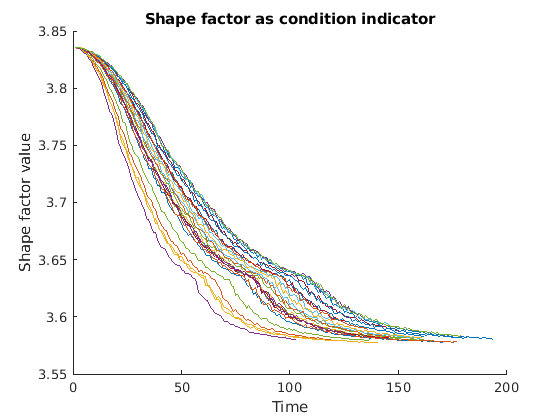

figure
ii = 0:1:25;
for i = ii
    var = rul_featuretable(rul_featuretable.Id == i, :);
    hold on
    plot(var.Time, var.("FlowContraction_stats/ShapeFactor"))
end
hold off
title("Shape factor as condition indicator")
xlabel("Time")
ylabel("Shape factor value")

### Split data to train and test datasets

%rul_featuretable(rul_featuretable.Id == 1, :)
i_train = rul_featuretable.Id == 5:25;
n = size(i_train);
n = n(2);
var = i_train(:,1);
for i = 1:1:(n-1)
    tmp = i_train(:,i) | i_train(:,i+1);
    var =  var | tmp;
end
i_train = var;
i_test = rul_featuretable.Id == 0:5;
n = size(i_test);
n = n(2);
var = i_test(:,1);
for i = 1:1:(n-1)
    tmp = i_test(:,i) | i_test(:,i+1);
    var =  var | tmp;
end
i_test = var;


train_data = rul_featuretable(var, :);
test_data = rul_featuretable(i_test, :);

#### Adjusting data for model

for i = 1:1:25
    tmp = rul_featuretable(rul_featuretable.Id == i, ["Time", "FlowContraction_stats/ShapeFactor"]);
    train_arr{i} = table(tmp.Time, tmp.("FlowContraction_stats/ShapeFactor"), 'VariableNames', ["Time", "Condition"]);
end

train_arr = train_arr';
test_data = rul_featuretable(rul_featuretable.Id == 0, "FlowContraction_stats/ShapeFactor").("FlowContraction_stats/ShapeFactor");

### Fit Residual Similarity Model

mdl = residualSimilarityModel('Method',"arma3",'LifeTimeUnit',"cycles");

fit(mdl, train_arr, "Time", "Condition")


#### Evaluate Model Perfomance

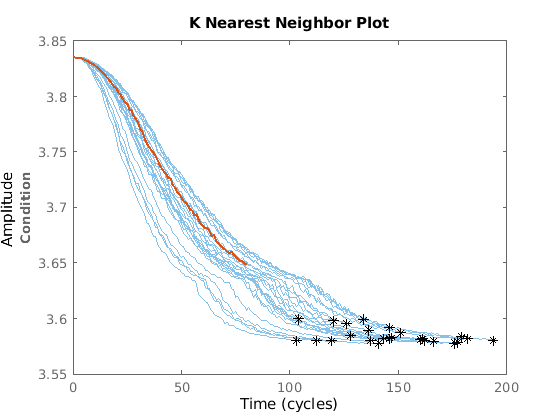

breakpoint = [0.5 0.7 0.9];
bpidx = 1;
test_data_50 = test_data(1:ceil(end*breakpoint(bpidx)));
true_rul_50 = length(test_data) - length(test_data_50);
[est_rul, ci_rul, pdf_rul] = predictRUL(mdl, test_data_50);
figure
compare(mdl, test_data_50)

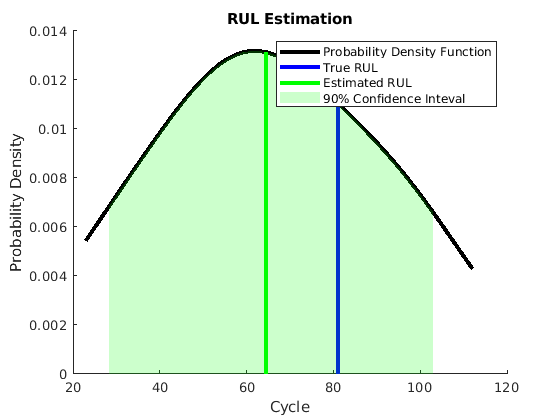

figure
helper_rul_distribution(true_rul_50, est_rul, pdf_rul, ci_rul)

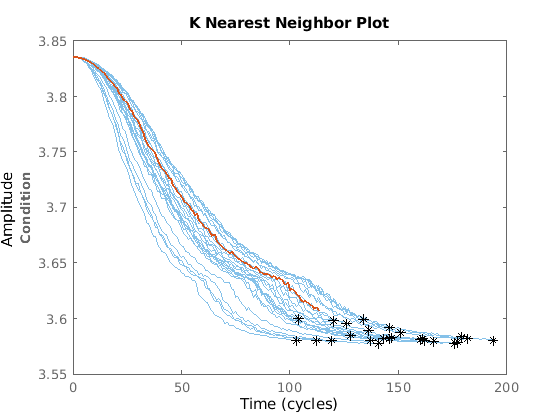

bpidx = 2;
test_data_70 = test_data(1:ceil(end*breakpoint(bpidx)));
true_rul_70 = length(test_data) - length(test_data_70);
[est_rul, ci_rul, pdf_rul] = predictRUL(mdl, test_data_70);
figure
compare(mdl, test_data_70)

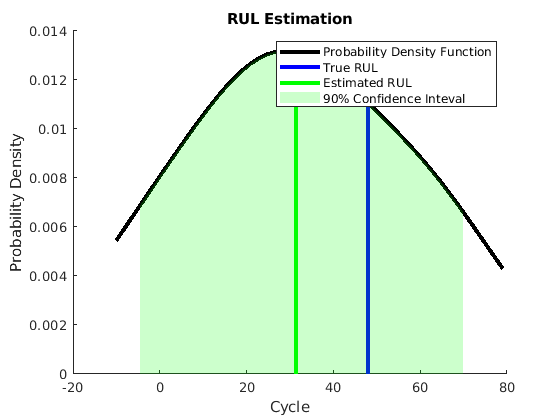

figure
helper_rul_distribution(true_rul_70, est_rul, pdf_rul, ci_rul)

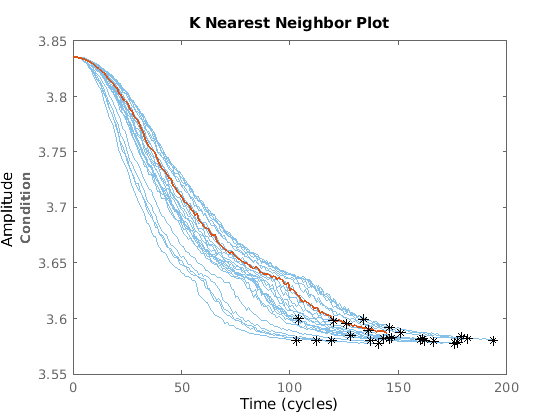

bpidx = 3;
test_data_90 = test_data(1:ceil(end*breakpoint(bpidx)));
true_rul_90 = length(test_data) - length(test_data_90);
[est_rul, ci_rul, pdf_rul] = predictRUL(mdl, test_data_90);
figure
compare(mdl, test_data_90)

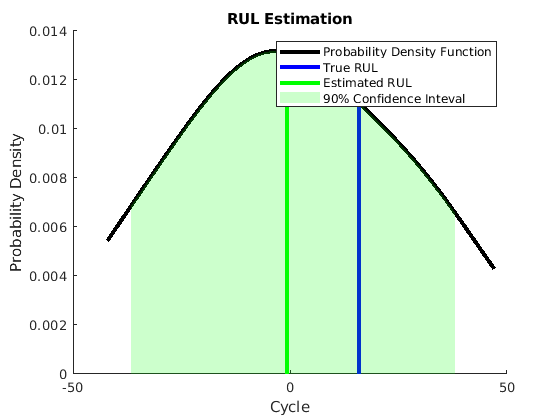

figure
helper_rul_distribution(true_rul_90, est_rul, pdf_rul, ci_rul)

### Conclusion

## Predict RUL Using Pairwise Similarity Model

mdl = pairwiseSimilarityModel('Method',"dtw",'Distance',"absolute",'LifeTimeUnit',"cycles");

Train the similarity model using the training data. Specify the names of the life time and data variables.

fit(mdl,train_arr,"Time","Condition")

[est_rul, ci_rul, pdf_rul] = predictRUL(mdl, test_data_50);
figure
compare(mdl, test_data_50)

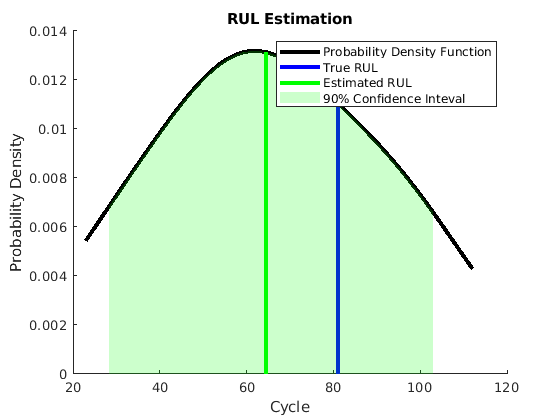

figure
helper_rul_distribution(true_rul_50, est_rul, pdf_rul, ci_rul)

[est_rul, ci_rul, pdf_rul] = predictRUL(mdl, test_data_70);
figure
compare(mdl, test_data_70)

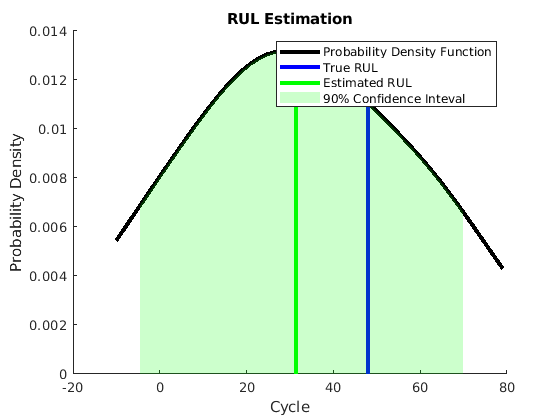

figure
helper_rul_distribution(true_rul_70, est_rul, pdf_rul, ci_rul)


[est_rul, ci_rul, pdf_rul] = predictRUL(mdl, test_data_90);
figure
compare(mdl, test_data_90)

figure
helper_rul_distribution(true_rul_90, est_rul, pdf_rul, ci_rul)

## Predict RUL Using Linear Degradation Model

This example shows how the model can be updated recursively in each step and predict remaining useful life before reaching some threshold.

mdl = linearDegradationModel('LifeTimeUnit', "cycles");
fit(mdl, train_arr, 'Time', 'Condition')
threshold = 3.6;
exp_test_data = rul_featuretable(rul_featuretable.Id == 0, ["Time", "FlowContraction_stats/ShapeFactor"]);
exp_test_data = table(exp_test_data.Time, exp_test_data.("FlowContraction_stats/ShapeFactor"), 'VariableNames', ["Time", "Condition"]);


cycles_done = 100;
for i = 1:cycles_done
    tmp = exp_test_data(i,:);
    update(mdl, tmp);
end

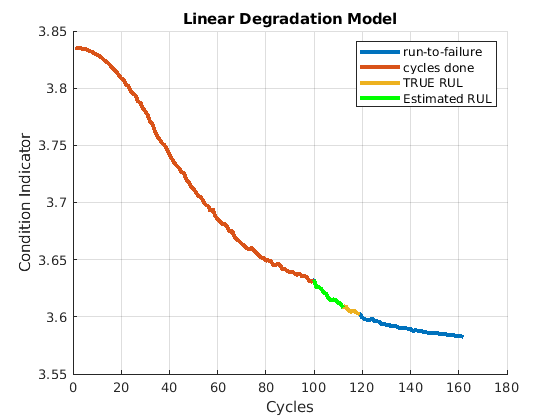

est_rul = predictRUL(mdl, threshold);
true_rul = table2array(exp_test_data(:,"Condition"));
true_rul = true_rul(true_rul > threshold);
true_rul_cycles = numel(true_rul) - cycles_done;

figure
hold on
plot(exp_test_data.Condition, 'LineWidth', 3)
plot(true_rul(1:cycles_done), 'LineWidth', 3)
x_tmp = cycles_done:(cycles_done-1 + length(true_rul(cycles_done:end)));
x_tmp = x_tmp';
y_tmp = true_rul(cycles_done:end);
plot(x_tmp, y_tmp, 'LineWidth', 3)

x_tmp = cycles_done:(cycles_done-1 + length(true_rul(cycles_done:cycles_done + round(est_rul))));
x_tmp = x_tmp';
y_tmp = true_rul(cycles_done:cycles_done+round(est_rul));
plot(x_tmp, y_tmp, 'g-', 'LineWidth',  3)

legend("run-to-failure", "cycles done", "TRUE RUL", "Estimated RUL")
title("Linear Degradation Model")
xlabel("Cycles")
ylabel("Condition Indicator")
grid on
hold off

fprintf("Estimated RUL: %.2f \n True RUL: %d \n", est_rul, true_rul_cycles)

Estimated RUL: 11.68 
 True RUL: 19 


## Functions

function helper_rul_distribution(true_rul, est_rul, pdf_rul, ci_rul)

hold on
plot(pdf_rul.RUL, pdf_rul.ProbabilityDensity, 'k', 'LineWidth', 3);
idx = find(pdf_rul.RUL > true_rul, 1, 'first');
if isempty(idx)
    y = pdf_rul.ProbabilityDensity(end);
else
    y = pdf_rul.ProbabilityDensity(idx);
end
plot([true_rul, true_rul], [0, y], 'b', 'LineWidth',3);
idx = find(pdf_rul.RUL > est_rul, 1, 'first');
if isempty(idx)
    y = pdf_rul.ProbabilityDensity(end);
else
    y = pdf_rul.ProbabilityDensity(idx);
end
plot([est_rul, est_rul], [0, y], 'g', 'LineWidth', 3);
idx = pdf_rul.RUL >= ci_rul(1) & pdf_rul.RUL<=ci_rul(2);
area(pdf_rul.RUL(idx), pdf_rul.ProbabilityDensity(idx), ...
    'FaceAlpha', 0.2, 'FaceColor', 'g', 'EdgeColor', 'none');
hold off
legend('Probability Density Function', 'True RUL', 'Estimated RUL', '90% Confidence Inteval');
xlabel('Cycle')
ylabel('Probability Density')
title('RUL Estimation')
end

function [dataTrain, dataTest] = split_dataset(data)
    cv = cvpartition(size(data,1), 'HoldOut', 0.3);
    idx = cv.test;      
    dataTrain = data(~idx, :);
    dataTest = data(idx, :);
end

function [accuracy] = confusion_matrix_plot_handler(mdl, features)
    required_features = mdl.RequiredVariables;
    targetLabels = features(:,"Label");
    inputTable = features(:, required_features);
    predictedLabels = mdl.predictFcn(inputTable);
    [C,order] = confusionmat(table2array(targetLabels),predictedLabels);
    accuracy = sum(table2array(targetLabels) == predictedLabels)/numel(predictedLabels);
    fprintf("Accuracy is %0.2f %% \n", accuracy*100)
    figure
    confusionchart(C, order)
end

function ensemble = handler_fix_datastore(ensemble)
% Append data
ensemble.DataVariables = [ensemble.DataVariables; "Time"; "Id"];

reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    cycle = data.Cycle{1,1}.Data;
    id = data.ID{1,1}.Data;
    writeToLastMemberRead(ensemble, "Time", cycle);
    writeToLastMemberRead(ensemble, "Id", id);
    disp(string(progress(ensemble)*100) + "% Done");
end
end

function ensemble = fix_label(ensemble)
reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    lab = data.Label{1,1};
    writeToLastMemberRead(ensemble, "Label", lab);
end
end


function signal = sim_signal_extract(signal)
    name = signal.Name;
    signal = ts2timetable(signal).(string(name))(1:end-1);
end

function [] = save_data(path, data, i)
    filename = path + "data_" + string(i) + ".mat";
    save(filename, "data")
end

function [label, r_pos_tt, r_vel_tt, r_fe_tt, r_fc_tt] = generate_residuals(reference, member, t)
    Ts = 1e-3;
    label = string(member.Label{1,1});
    position = member.LeverPosition{1,1};
    velocity = position; velocity.Data = [diff(position.Data)/Ts; 0];
    flow_ex = member.FlowExtrusion{1,1};
    flow_con = member.FlowContraction{1,1};
    
    r_pos = reference.position-position.Data;
    r_vel = reference.velocity-velocity.Data;
    r_fe = reference.flow_ex-flow_ex.Data;
    r_fc = reference.flow_con-flow_con.Data;
    
    r_pos_tt = timetable(r_pos, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_vel_tt = timetable(r_vel, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_fe_tt = timetable(r_fe, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_fc_tt = timetable(r_fc, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
end
